# Plotting Beacon data in Global Frame

Objective: This script will show you how to read the Beacon data and transform the data from the sensor frame to the robot frame using *transform_points*. This will then plot the sensed beacon locations in the **global frame**. 

Execise:

Using the Simulator, get the CreateRobot object that represents the current state of the robot 

Initialize Robot Constants. The camera is situated directly on the edge of the robot directly in front (along the x-axis of the robot frame) and is oriented in the same direction. This is what defines the origin of the sensor reference frame. Define the beacon pose to the variable beacon_pose. 

**COMPLETE THE CODE BELOW**

%Initialize robot constants
robotRadius = robotObj.radius;
beacon_pose = [robotRadius; 0; 0];


Read the beacon data. 

%Read Beacon Data
tags = RealSenseTag(robotObj);

Read the robot pose

%Read the current position of the robot from the overhead
%  x, y and th, not a vector containing those values
[x, y, th]= genOverhead(robotObj);
robot_pose = [x; y; th];  

Just like the LIDAR sensor, you will need to transform the output of the sensor from the sensor frame to the global frame. Using the *transform_points* function, transform the data from the sensor Frame to the robot Frame and assign to the variable dataxy_robot. Then transform the data from robot to global frame and assign to the variable dataxy_global. . A for loop is used to transform each identified tag. 

**COMPLETE THE CODE BELOW**


for i = 1:size(tags,1)
    beacon_number = round(tags(i,2)); % Gets beacon number
    dataxy_sensor = tags(i, 3:4)'; %Read the position from each beacon
    
    % Transform data to robot frame
    dataxy_robot = transform_points(beacon_pose,dataxy_sensor);%Insert your code here
    % Transform data to global frame
    dataxy_global = transform_points(robot_pose, dataxy_robot); %Insert your code here
end
  

The code below creates a plot of each beacon in the global frame. 

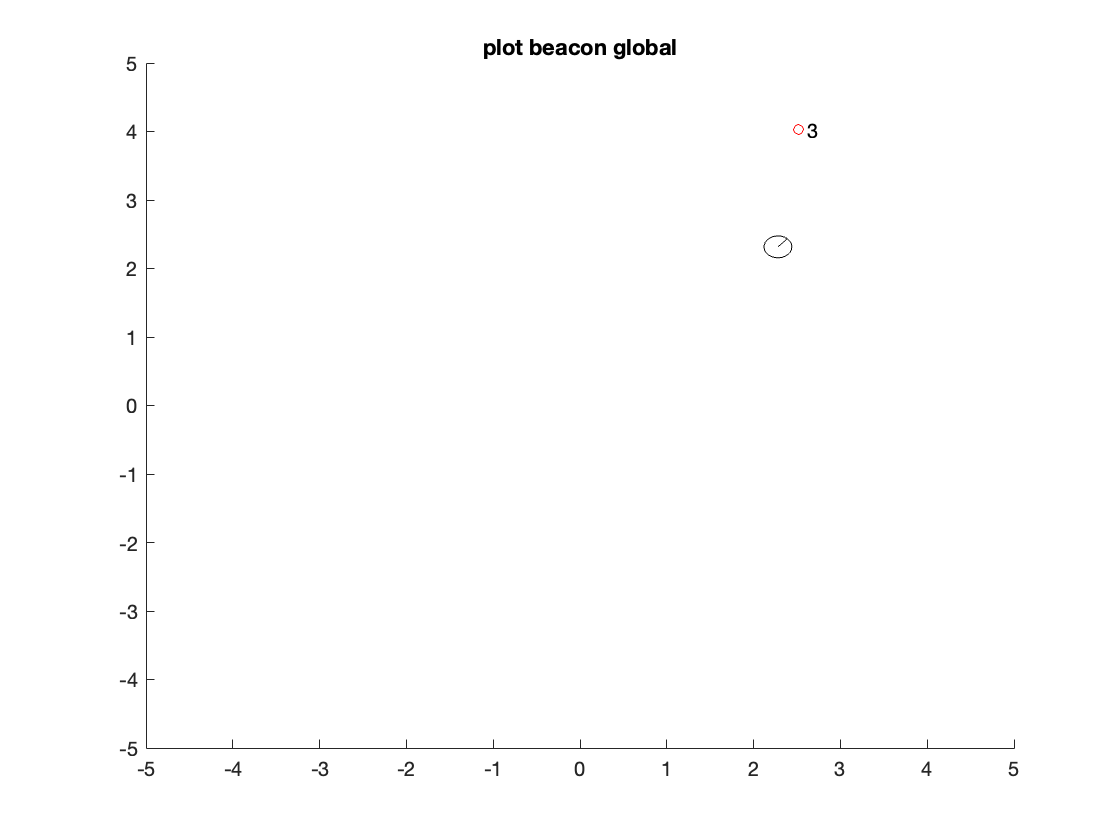

%Plot
figure; 
hold on ;
for i = 1:size(tags,1)  
    plot(dataxy_global(1),dataxy_global(2),'ro','Markersize',5);
    text(dataxy_global(1)+.1,dataxy_global(2),num2str(beacon_number));
end
th = linspace(0,2*pi,30);
plot(robot_pose(1)+robotRadius*cos(th),robot_pose(2)+robotRadius*sin(th),'k-')
plot([robot_pose(1),robot_pose(1)+robotRadius*cos(robot_pose(3))], ...
    [robot_pose(2),robot_pose(2)+robotRadius*sin(robot_pose(3))],'k-')

axis([-5 5 -5 5])
title('plot beacon global')
set(gcf,'Visible','on'); 

Expected Results: Because you are plotting the beacon data in the **global frame**, you should see the beacon plotted just as you would see the beacons in the map in the simulator.

Check your Comprehension: Is the beacon position plotted as expected? Move the robot around the map facing different beacons and compare the plots. By moving the robot around, can you define the sensor footprint of the beacon sensor?